# **demo16 of Im2mesh package**

demo16 - Add mesh seeds/nodes

Cite as: Ma, J., & Li, Y. (2025). Im2mesh: A MATLAB/Octave package for generating finite element mesh based on 2D multi-phase image (2.1.5). Zenodo. [https://doi.org/10.5281/zenodo.14847059](https://doi.org/10.5281/zenodo.14847059)

Jiexian Ma, mjx0799@gmail.com. [Project website](https://github.com/mjx888/im2mesh).

## Note

I suggest familiarizing yourself with Im2mesh_GUI before learning Im2mesh package. With graphical user interface, Im2mesh_GUI will help you better understand the workflow and parameters of Im2mesh package.

Im2mesh_GUI: [https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh](https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh)

If you are using Im2mesh package in MATLAB,  you need to install MATLAB Image Processing Toolbox and Mapping Toolbox because Im2mesh package use a few functions in these toolboxes.

## Setup

Before we start, please set folder "Im2mesh_Matlab" as your current folder of MATLAB.

clearvars

Set default image size.

x = 250; y = 250; width = 250; height = 250;
set(groot, 'DefaultFigurePosition', [x,y,width,height])
% To reset:
% set(groot, 'DefaultFigurePosition', 'factory')

Function poly2mesh use a mesh generator called [MESH2D](https://github.com/dengwirda/mesh2d) (developed by Darren Engwirda). We can use the following command to add the folder 'mesh2d-master' to the path of MATLAB. 

addpath(genpath('mesh2d-master'))

## Overview

Please take a look at demo14 before starting demo16.

In Im2mesh package, mesh seeds/nodes are defined as markers that you place along the edges of a region. We use mesh seeds to specify target mesh density in a region.

There are two different cases for adding mesh seeds. We will show them in this demo.

- Case 1. The coordniates of the seeds to be added is known.

- Case 2. The coordniates of the seeds to be added is unknown.

We have demostrated how to create polygonal boundary in previous demo. There are two approaches:

- demo01 - create polygonal boundary based on 2d image.

- demo14 - create polygonal boundary from polyshape objects.

In this demo, we'll use polyshape to create polygonal boundary, and then add mesh seeds/nodes to boundary. For boundaries created based on 2d image, the workflow of adding mesh seeds/nodes is the same.

## Case 1. Coordniates of the seeds to be added is known

### Define polyshape and create boundary

Define a cell array of polyshape objects

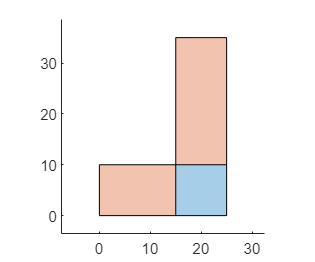

% create polyshape
vert1 = [ 0 0; 15 0; 15 10; 0 10 ];
ps1 = polyshape(vert1);

vert2 = [15 0] + [ 0 0; 10 0; 10 10; 0 10 ];
ps2 = polyshape(vert2);

vert3 = [15 10] + [ 0 0; 10 0; 10 25; 0 25 ];
ps3 = polyshape(vert3);

ps13 = union( ps1, ps3 );
psCell = { ps2; ps13 };

% plot psCell
figure
hold on; axis equal;
for i = 1: length(psCell)
    plot(psCell{i});
end
hold off

We saw 2 phases (or 2 parts) and 3 regions.

Create polygonal boundary from polyshape

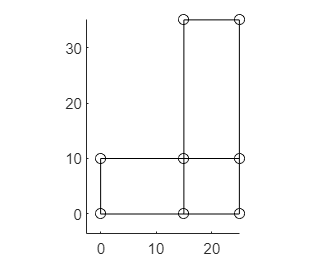

% bounds is a nested cell array of polygonal boundary
bounds = polyshape2bound(psCell);

tol_intersect = 1e-6;   % distance tolerance for intersect
bounds = addIntersectPnts( bounds, tol_intersect );

% plot boundaries and show all vertices
plotBounds(bounds,false,'ko-')

We can use function xyRange to get the range of x y coordinate in boundary.

[xmin, xmax, ymin, ymax] = xyRange( bounds )

xmin = 0

xmax = 25

ymin = 0

ymax = 35

### Add a midpoint to the bottom edge

Suppose we want to add a midpoint to the bottom edge of 'bounds' .

Based on xmin, xmax, ymin, ymax, we know that the midpoint in the bottom edge of 'bounds' would be

xMid = (xmin + xmax)/2;
yMid = ymin;

We can use function addPnt2Bound to add point (xMid,yMid) to boundary. 

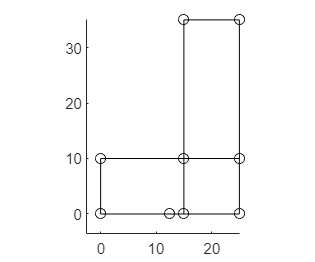

point = [xMid, yMid];

tol_dist = 1e-2;    % distance tolerance
newB = addPnt2Bound( point, bounds, tol_dist );

% show all vertices
plotBounds( newB, false, 'ko-' );  

We saw that the midpoint of the bottom edge is added to the boundary. 

When we generate finite element mesh, the mesh will have this point in the vertices. 

### Add a point near the bottom edge

The point to be added does not have to lie exactly on the pristine boundary. The point can have some distance away from the pristine boundary. Check the following example. 

Here we set distance tolerance 'tol_dist' to 5. If the shortest distance between the point and the pristine boundary is less than 'tol_dist', the point will be added to the boundary. Otherwise, the point will not be added.

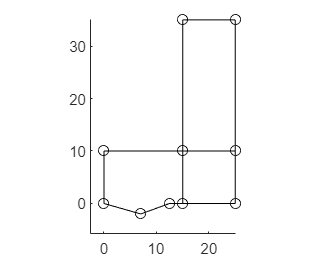

point = [7,-2];
tol_dist = 5;    % distance tolerance
newB = addPnt2Bound( point, newB, tol_dist );

% show all vertices
plotBounds( newB, false, 'ko-' );

### Generate mesh

[ poly_node, poly_edge ] = getPolyNodeEdge( newB );

hmax = 3; 
mesh_kind = 'delaunay'; % method used to create mesh size function
grad_limit = 0.25;
[ vert,tria,tnum ] = poly2mesh( poly_node, poly_edge, hmax, mesh_kind, grad_limit );

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          1                 12                  8
          4                 14                 11


 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          5                 50                  8
         10                 51                139
         11                 51                141


 Smooth triangulation...

 -------------------------------------------------------
      |ITER.|          |MOVE(X)|          |DTRI(X)|     
 -------------------------------------------------------
          4                 38                141
          8                  1                141



Plot mesh.

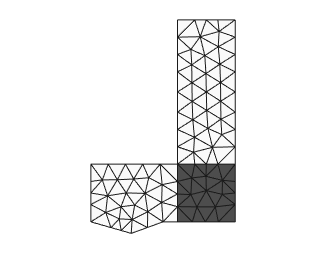

plotMeshes(vert,tria,tnum);

## Case 2. Coordniates of the seeds to be added is unknown

We will use the same geometry for demostration.

% plot boundaries and show all vertices
plotBounds(bounds,false,'ko-')

### Find edges we interested in

Suppose we are interested in the bottom edge and the right edge in the topmost rectangle. Let's find these edges in 'bounds'.

bounds is a nested cell array of polygonal boundaries. 

bounds

bounds = 2×1 cell array
    {1×1 cell}
    {2×1 cell}


We can plot polygons one by one.

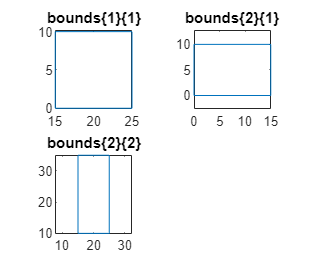

figure;
counter = 1;

for i = 1: length(bounds)
    for j = 1: length(bounds{i})
        subplot(2,2,counter); 

        poly = bounds{i}{j};
        plot( poly(:,1), poly(:,2) ); axis equal;
        title(['bounds\{', num2str(i), '\}\{', num2str(j), '\}']);

        counter = counter + 1;
    end
end

The edge we interested in belongs to bounds{2}{2}. 

bounds{2}{2}

ans =     15    10
    25    10
    25    35
    15    35
    15    10


Let's plot it.

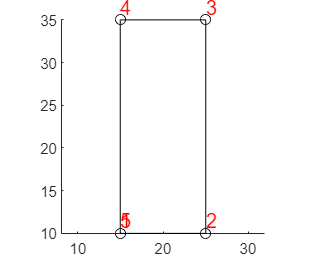

poly = bounds{2}{2};

figure; hold on; axis equal
plot( poly(:,1), poly(:,2), 'ko-' );

% add numbering
for i = 1: length(poly)
    text( poly(i,1), poly(i,2), num2str(i), ...
        'HorizontalAlignment', 'left', ...
        'VerticalAlignment', 'bottom', ...
        'FontSize', 12, 'Color', 'red');
end
hold off

In the figure, the numberings of the 1st and the last vertex overlap.

### Method 1. Add seed by inserting midpoint

We can use function **insertMidPnt** to add seeds.

The edge we interested in is between vertex 1 and vertex 3 in the polygon

Let's extract it. 

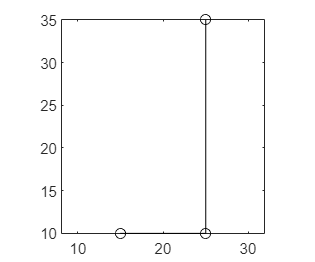

index = 1:3;
polyline = poly( index, : );
plot( polyline(:,1), polyline(:,2), 'ko-' ); axis equal

Then, we can add seeds to the interested edges by repeatedly inserting midpoints to edges. We do this by function insertMidPnt.

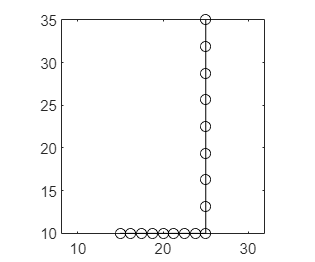

iters = 3;
polyline = insertMidPnt( polyline, iters );
plot( polyline(:,1), polyline(:,2), 'ko-' ); axis equal

**Add points to bounday**

Use function addPnt2Bound to add the points to the bounday.

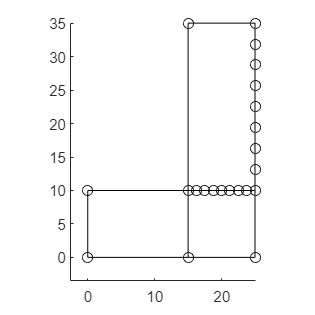

tol_dist = 1e-2;    % distance tolerance
newB = addPnt2Bound( polyline, bounds, tol_dist );

% show all vertices
plotBounds( newB, false, 'ko-' );

Awesome! But we notice that the space between seeds in different edges are different. This is not good.

### Method 2. Add uniform seeds

We can use function **insertEleSizeSeed** to add better uniform seeds. 

The edge we interested in is between vertex 1 and vertex 3 in the polygon. Let's extract it. 

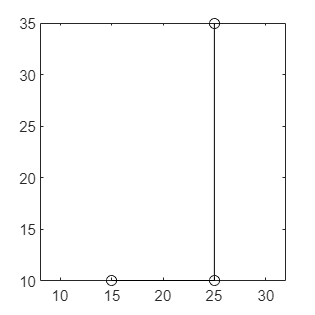

index = 1:3;
polyline = poly( index, : );
plot( polyline(:,1), polyline(:,2), 'ko-' ); axis equal

Then, we can add uniform seeds to the interested edges by function insertEleSizeSeed. We can specify the space between seeds.

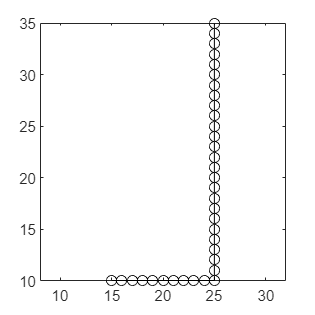

target_size = 1;  % space between seeds
polyline = insertEleSizeSeed( polyline, target_size );

plot( polyline(:,1), polyline(:,2), 'ko-' ); axis equal

Very good! The space between seeds in different edges are the same now.

**Add points to bounday**

Use function addPnt2Bound to add the points to the bounday.

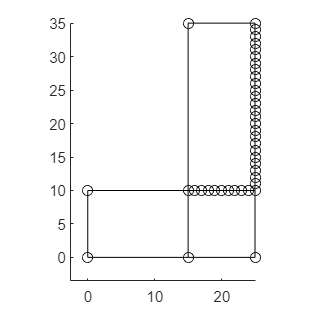

tol_dist = 1e-2;    % distance tolerance
newB = addPnt2Bound( polyline, bounds, tol_dist );

% show all vertices
plotBounds( newB, false, 'ko-' );

**Generate mesh**

[ poly_node, poly_edge ] = getPolyNodeEdge( newB );

hmax = 3; 
mesh_kind = 'delaunay'; % method used to create mesh size function
grad_limit = 0.25;
[ vert,tria,tnum ] = poly2mesh( poly_node, poly_edge, hmax, mesh_kind, grad_limit );

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          2                 44                 48
         10                 57                126
         11                 57                128


 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          6                 80                 48
         10                 80                287
         13                 80                369


 Smooth triangulation...

 -------------------------------------------------------
      |ITER.|          |MOVE(X)|          |DTRI(X)|     
 -------------------------------------------------------
          4                110                367
          8                 39                367



Plot mesh.

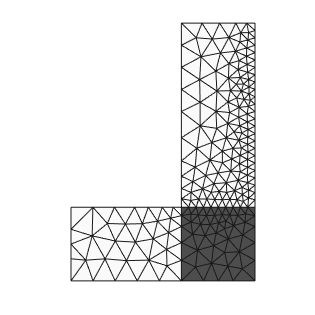

plotMeshes(vert,tria,tnum);

Awesome!

**Add seeds to all boundaries**

We can also add uniform seeds to all boundaries, which may be useful in some cases.

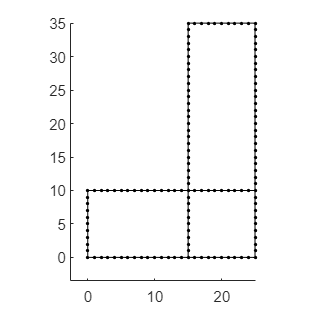

target_size = 1;  % space between seeds
n_digit = 2;
newB = bounds;

for i = 1: length(newB)
	for j = 1: length(newB{i})
		newB{i}{j} = insertEleSizeSeed( newB{i}{j}, target_size );
        
		newB{i}{j} = round( newB{i}{j}, n_digit );
	end
end

% show all vertices
plotBounds( newB, false, 'k.-' );

Generate mesh

[ poly_node, poly_edge ] = getPolyNodeEdge( newB );

hmax = 3; 
mesh_kind = 'delaunay'; % method used to create mesh size function
grad_limit = 0.25;
[ vert,tria,tnum ] = poly2mesh( poly_node, poly_edge, hmax, mesh_kind, grad_limit );

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          1                140                154
          9                140                316


 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          1                140                154
         10                140                758
         10                140                758


 Smooth triangulation...

 -------------------------------------------------------
      |ITER.|          |MOVE(X)|          |DTRI(X)|     
 -------------------------------------------------------
          4                252                748
          8                 19                748



Plot mesh.

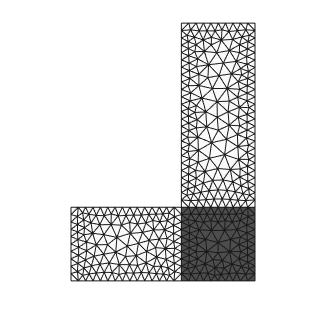

plotMeshes(vert,tria,tnum);

### Method 3. Add biased seeds

The above example is with uniform seeds. How about biased seeds (non-uniform distributed)?

We can use function **insertBiasedSeed** to do that.

Suppose we are interested in the edge between vertex 1 and vertex 2 in the polygon.

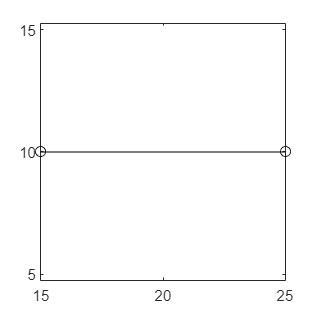

index = 1:2;
edge = poly( index, : );
plot( edge(:,1), edge(:,2), 'ko-' ); axis equal

We can use function insertBiasedSeed to insert biased seeds into a single edge. Note that the 1st input of function insertBiasedSeed should be a 2-by-2 array (two points), and the output result depends on the vertex ordering in the input edge.

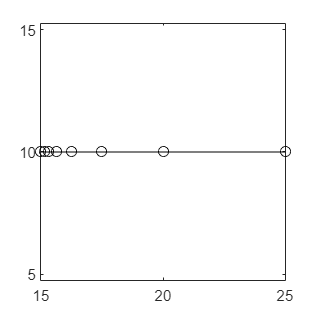

iters = 6;
ratio = 0.5;
edge = insertBiasedSeed( edge, iters, ratio );

plot( edge(:,1), edge(:,2), 'ko-' ); axis equal

Let's use function insertMidPnt to make seeds denser.

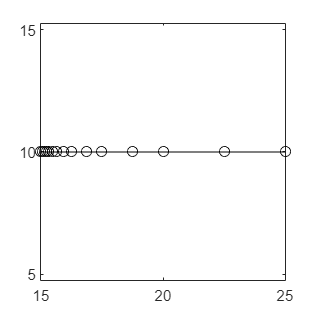

iters = 1;
edge = insertMidPnt( edge, iters );

plot( edge(:,1), edge(:,2), 'ko-' ); axis equal

**Add points to bounday**

Use function addPnt2Bound to add the points to the bounday.

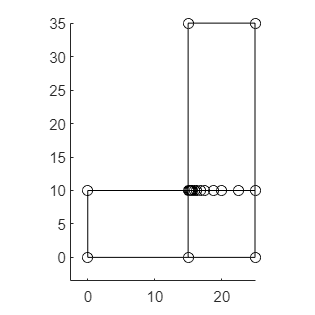

tol_dist = 1e-2;    % distance tolerance
newB = addPnt2Bound( edge, bounds, tol_dist );

% show all vertices
plotBounds( newB, false, 'ko-' );

**Generate mesh**

[ poly_node, poly_edge ] = getPolyNodeEdge( newB );

hmax = 3; 
mesh_kind = 'delaunay'; % method used to create mesh size function
grad_limit = 0.25;
[ vert,tria,tnum ] = poly2mesh( poly_node, poly_edge, hmax, mesh_kind, grad_limit );

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          1                 23                 32
         10                 43                 98
         13                 45                110


 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
         10                 97                 32
         10                 97                 32
         20                100                594
         22                100                604


 Smooth triangulation...

 -------------------------------------------------------
      |ITER.|          |MOVE(X)|          |DTRI(X)|     
 -------------------------------------------------------
          4                144                600
     

Plot mesh.

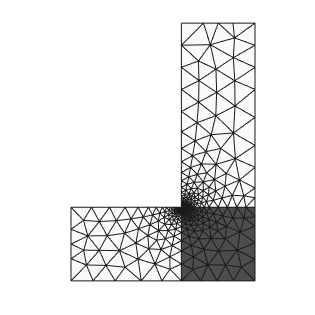

plotMeshes(vert,tria,tnum);

Awesome!

% reset image size
set(groot, 'DefaultFigurePosition', 'factory')

% end of demo